# Números en MATLAB

Las números en MATLAB incluyen **enteros** con signo y sin signo, y números de **punto flotante** de precisión simple y precisión doble. De forma predeterminada, MATLAB almacena todos los valores numéricos como **punto flotante de precisión doble**.

En otras palabras, tenemos dos tipos de números:

- Enteros (sin decimales)

- Punto flotante (con decimales)

## Números de punto flotante (o decimales)

Los números de punto flotante, o de coma flotante, son comúnmente conocidos también como los **números reales dentro de la programación**.

Las funciones para definir números de punto flotante son:

- `double` (por defecto): números de punto flotante de precisión doble de hasta 52 cifras decimales.

- `single`: números de punto flotante de precisión sencilla de hasta 23 cifras decimales.

### Ejemplos

#### Número $\pi$

El número $\pi$ dentro de MATLAB está definido como la constante `pi`.

% Forma alternativa.
% fprintf("%.49f", double(pi))

fprintf("%.49f", pi)
fprintf("%.23f", single(pi))

#### Número de Euler $e$

El número de Euler se crea utilizando la función exponencial $e^x$, lo que dentro de MATLAB se realiza con la función `exp`.

% Forma alternativa.
% fprintf("%.51f", double(exp(1)))

fprintf("%.51f", exp(1))
fprintf("%.21f", single(exp(1)))

#### Número $\sqrt{2}$

La raíz cuadrada de un número se obtiene con la función `sqrt`.

% Forma alternativa.
% fprintf("%.53f", double(sqrt(2)))

fprintf("%.53f", sqrt(2))
fprintf("%.24f", single(sqrt(2)))

### Notación científica

La **notación científica**, también denominada notación exponencial, es una forma de escribir los números basada en potencias de 10, lo que resulta especialmente útil para la **representación de valores muy grandes o pequeños**, así como para el cálculo con ellos.

Por ejemplo, la masa del electrón es $0\ldotp 000\;000\;000\;000\;000\;000\;000\;000\;000\;000\;911\;\textrm{kg}=9\ldotp 11\times {10}^{-31} \;\textrm{kg}$. Otro ejemplo, la mayor distancia observable del universo es $740\;000\;000\;000\;000\;000\;000\;000\;000\;\mathrm{m}=7\ldotp 4\times {10}^{26} \;\mathrm{m}$.

Dentro de MATLAB se podrían escribir directamente la expresiones:

Sin embargo, en lugar de ello se puede utilizar la letra `e` y luego indicar la potencia.

% Número original.
0.000000000000000000000000000000911
% Número con notación científica.
9.11e-31
% Número original.
740000000000000000000000000
% Número con notación científica.
7.4e26

### Números de punto flotante máximos y mínimos

Matemáticamente hablando, es posible escribir números tan grandes y tan pequeños como queramos. "**El papel aguanta todo**", dijo algún sabio. Sin embargo, como los números dentro de la programación son variables, y por tanto, espacio de memoria dentro de la computadora, y la computadora no tiene espacio infinito, es necesario establecer un límite superior e inferior de los números reales dentro de MATLAB.

Para conocer el número de punto flotante máximo y mínimo se utiliza la función `realmax` y `realmin`, respectivamente; tanto para los números tipo `double` como para los números tipo `single`.

realmax double
realmax single
realmin double
realmin single

#### ¿Qué sucede si se excede el límite máximo o mínimo?

Si se realizan operaciones tal que se excede el límite máximo, entonces el resultado es tan grande que MATLAB ya no lo procesa y devuelve `Inf` (infinito). Este caso se conoce como **desbordamiento**.

1.79e200 * 1e108    % A punto de llegar al límite máximo con números double.
1.80e200 * 1e108    % Desbordamiento.

Por el contrario, si el número es tan pequeño que excede el límite mínimo, entonces MATLAB ya no lo procesa y devuelve `0`. Este caso se conoce como **subdesbordamiento**.

1e-215 * 1e-108     % Menor que el límite mínimo con número double.
realmin double      % Límite mínimo teórico
1e-216 * 1e-108     % Subdesbordamiento

Como se puede observar, en ocasiones se puede llegar a los límites o sobrepasarlos y MATLAB sigue procesando información, hasta cuando se excede demasiado y ocurre el desbordamiento o subdesbordamiento.

Sin embargo, **no se recomienda en absoluto trabajar cerca de las fronteras de los límites de cada tipo de dato**.

## Números enteros

Existen dos tipos de números enteros en MATLAB: enteros con signo y enteros sin signo. La diferencia entre los números enteros con signo y sin signo es el número máximo que pueden guardar.

**Los números enteros sin signo guardan números el doble de grandes que sus contrapartes enteras con signo utilizando el mismo espacio de almacenamiento**.

Las funciones para definir **números enteros con signo** (`signed ``int``eger`) son:

- `int8`

- `int16`

- `int32`

- `int64`

Las funciones para definir **números enteros sin signo** (`u``nsigned ``int``eger`) son:

- `uint8`

- `uint16`

- `uint32`

- `uint64`

#### Observación

El número al final de cada función para definir números enteros indica el números de bits que ocupará la variable numérica entera. A mayor número de bits, mayor es el número entero que se puede generar.

#### ¿Cuándo utilizar números enteros con signo y sin signo?

Si el signo de la variable numérica es irrelevante, como la edad, entonces se debería crear la variable como número entero sin signo. Pero si sí importa el signo entonces se debería utilizar números enteros con signo.

### Ejemplos

int8(24)
int8(130)
uint8(130)
int16(36000)
uint16(3600)

#### Observación

Si se intenta crear un número entero a partir de un número decimal, la función redondeará el número decimal. Si la parte decimal es menor que 5 tomará el entero menor, pero si la parte decimal es mayor que 5 tomará el entero superior.

int32(2.49)
int32(2.50)

### Números enteros máximos y mínimos

Análogamente a los números de punto flotante, los números enteros también tiene un límite máximo y mínimo, dependiendo si son enteros con signo o enteros sin signo. Las funciones para conocer el límite máximo y mínimo para números enteros son `intmax` e `intmin`, respectivamente.

Los números enteros con signo tiene la mitad del límite superior que sus contrapartes sin signo.

intmax int8
intmax uint8
intmax int16
intmax uint16

Sin embargo, el límite inferior para números enteros con signo y sin signo sí es diferente. Como los números enteros sin signo no tienen eso, un signo, entonces su límite inferior es `0`. En cambio los números enteros con signo sí tienen un límite inferior.

intmin int8
intmin uint8
intmin int16
intmin uint16

#### ¿Qué sucede si se supera el límite superior o límite inferior?

Para los números enteros no ocurre un desbordamiento, únicamente devolverá el número máximo del tipo de entero con el que se esté trabajando.

int8(130)
uint8(260)

Tampoco ocurre un subdesbordamiento, únicamente devolverá el número mínimo del tipo de entero con el que se esté trabajando.

int8(-130)
uint8(-1)

## Función `class`

La función `class` retorna el nombre del **tipo de dato** (conocido también como **clase**) de la variable.

clear

load Tema02_Auxiliar01_VariablesNumericas.mat
who
class(altura)
class(dias)
class(prestamo)

## Operaciones aritméticas

Las operaciones aritméticas se realizan con los operadores usuales ya conocidos en matemática. Además, se debe indicar explícitamente las operaciones que se desea realizar.

A continuación se detallan las operaciones aritméticas y el porqué la tercera forma es la totalmente correcta dentro de MALTAB.

### Suma

Para sumar dos números se utiliza la función `plus` o la función `+`.

3 + 4
plus(3, 4)

### Resta

Para restar dos números se utiliza la función `minus` o la función `-`.

6 - 2
minus(6, 2)

### Producto

Para multiplicar dos números se utiliza la función `times` o la función `.*`.

3 .* 9
times(3, 9)

#### Observación

 Cuando se trata del **producto entre dos números** no es necesario añadir el punto `.` antes del asterisco `*`.

3 * 9

Sin embargo, esto es un caso particular. Más adelante se estudiará este tema con más detalle. De cualquier manera se recomienda **siempre añadir el punto** para evitar posibles errores cuando crece el código.

**Lo anterior mencionado aplica para las operaciones aritméticas de aquí en adelante.**

### Potencia

Para realizar la potencia entre dos números se utiliza la función `power` o la función `.^`.

2 .^ 3
power(2, 3)

### División

#### División derecha (división usual)

Para dividir dos números (de derecha a izquierda) se utiliza la función `rdivide` o la función `./`.

5 ./ 2
rdivide(5, 2)

#### División izquierda

Para dividir dos números (de izquierda a derecha) se utiliza la función `ldivide` o la función `.\`.

5 .\ 2
ldivide(5, 2)

### División entera

En la siguiente imagen se observan las partes de la división. Teniendo esto como base (y para recordar), a continuación se listan las funciones de la divisón entera.

**Figura 1.** Partes de una división

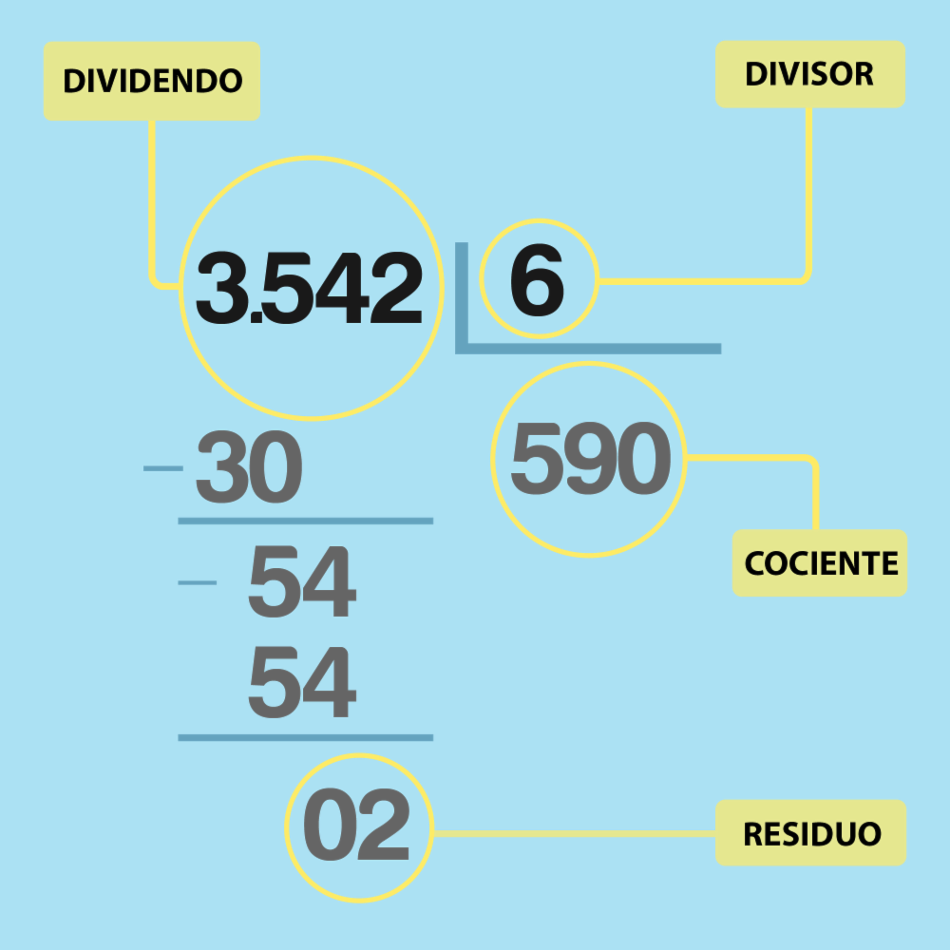

*Tomado de *[*GCF AprendeLibre*](https://aprendizaje.mec.edu.py/dw-recursos/system/content/12c54d4/matematicas/curso/como_dividir/en_que_consiste_una_division/2.do.html)*.*

Para obtener el cociente de la división entre dos números se utiliza la función `idivide`. **Al menos uno de los números con los cuales se realizará la división entera debe ser entero**.

n1 = int8(5);   % Entero con signo int8.

idivide(n1, 2)

#### Observación

Si se desea realizar la división entera entre dos números enteros, **ambos deben ser del mismo tipo**.

n2 = int8(2);

idivide(n1, n2)

### Remanente

Para obtener el remanente (o resto) de la división entre dos números se utiliza la función `mod` o la función `rem`.

mod(5, 2)
rem(5, 2)

#### ¿Cuál es la diferencia entre la función `rem` y la función `mod`?

La función `mod` produce un resultado que es cero o tiene el mismo signo que el divisor, mientras que la función `rem` produce un resultado que es cero o tiene el mismo signo que el dividendo.

% Evaluando cuando el divisor es negativo.
mod(5, -2)
rem(5, -2)
% Evaluando cuando el dividendo es negativo.
mod(-5, 2)
rem(-5, 2)

Otra diferencia es la convención cuando el divisor es cero. La función `mod` sigue la convención de que `mod(a, 0)` devuelve `a`, mientras que la función `rem` sigue la convención de que `rem(a, 0)` devuelve `NaN`.

mod(5, 0)
rem(5, 0)

## Orden de las operaciones aritméticas

El orden en el cual se llevan a cabo las operaciones aritméticas dentro de MATLAB es el mismo establecido en matemática.

- Paréntesis (desde lo más internos).

- Potencia.

- Multiplicación y división.

- Suma y resta.

En el caso de que hayan varias operaciones del mismo orden, entonces se realizarán las **operaciones de izquierda a derecha**.

4 - 3 * 20 - 3 * 4 - 2 + 4 / 2
(4 - 3) * 20 - 3 * 4 - (2 + 4) / 2
4 - 3 * (20 - 3 * 4 - (2 + 4)) / 2

#### Observación

Cuando se tiene una expresión "larga" como divisor o exponente, por ejemplo, se debe indicar explícitamente.

Por ejemplo, si se tiene la expresión $2^{xy} + 1$, entonces:

x = 2;
y = 3;

2.^x.*y + 1     % Forma incorrecta
2.^(x.*y) + 1   % Forma correcta

Es decir, MATLAB toma el primer valor para realizar la respectiva operación cuando no se indica explícitamente la operación deseada.

## Números complejos

Los números complejos dentro de MATLAB se definen en forma binomial y la unidad imaginaria tiene dos representaciones: `i` y `j`. Ambas representaciones son iguales a $\sqrt{-1}$, aunque la más usual es `i`.

Además, definir la parte imaginaria de un número complejo manualmente **es la única operación donde no se debe indicar explícitamente la multiplicación**.

Aunque MATLAB no generará un error, directamente mostrará un mensaje indicando que no es la manera adecuada de definir un número complejo manualmente.

2 + 3i
3 - 4i

### Funciones asociadas a los números complejos

MATLAB posee varias funciones para trabajar con números complejos. A continuación se detallan las más usadas.

#### Función `complex`

Permite generar un número complejo ingresando la parte real e imaginaria.

z = complex(3, -4)

#### Función `real`

Permite extraer la parte real de un número complejo.

real(z)

#### Función `imag`

Permite extraer la parte imaginaria de un número complejo.

imag(z)

#### Función `conj`

Permite obtener el conjugado de un número complejo.

conj(z)

#### Función `angle`

Permite obtener el argumento (o fase) de un número complejo.

angle(z)

#### Función `abs`

Permite obtener el módulo de un número complejo.

abs(z)

#### Observación

La función `abs` no se reserva únicamente para los números complejos. En realidad la función `abs` es la función valor absoluto.

abs(10)
abs(-5)

Sin embargo, el módulo de un vector se lo conoce en ocasiones como valor absoluto. Por esta razón se la puede utilizar también con números complejos.

## Formatos de visualización

Ahora que ya hemos revisado los números dentro de MALTAB, también es importante conocer las diferentes formas en que se los puede visualizar.

La función `format` permite cambiar la forma de visualizar los números. No los modifica, únicamente cambia su visualización.

A continuación se muestran los estilos disponibles.

**Figura 2.** Estilos de formato numérico

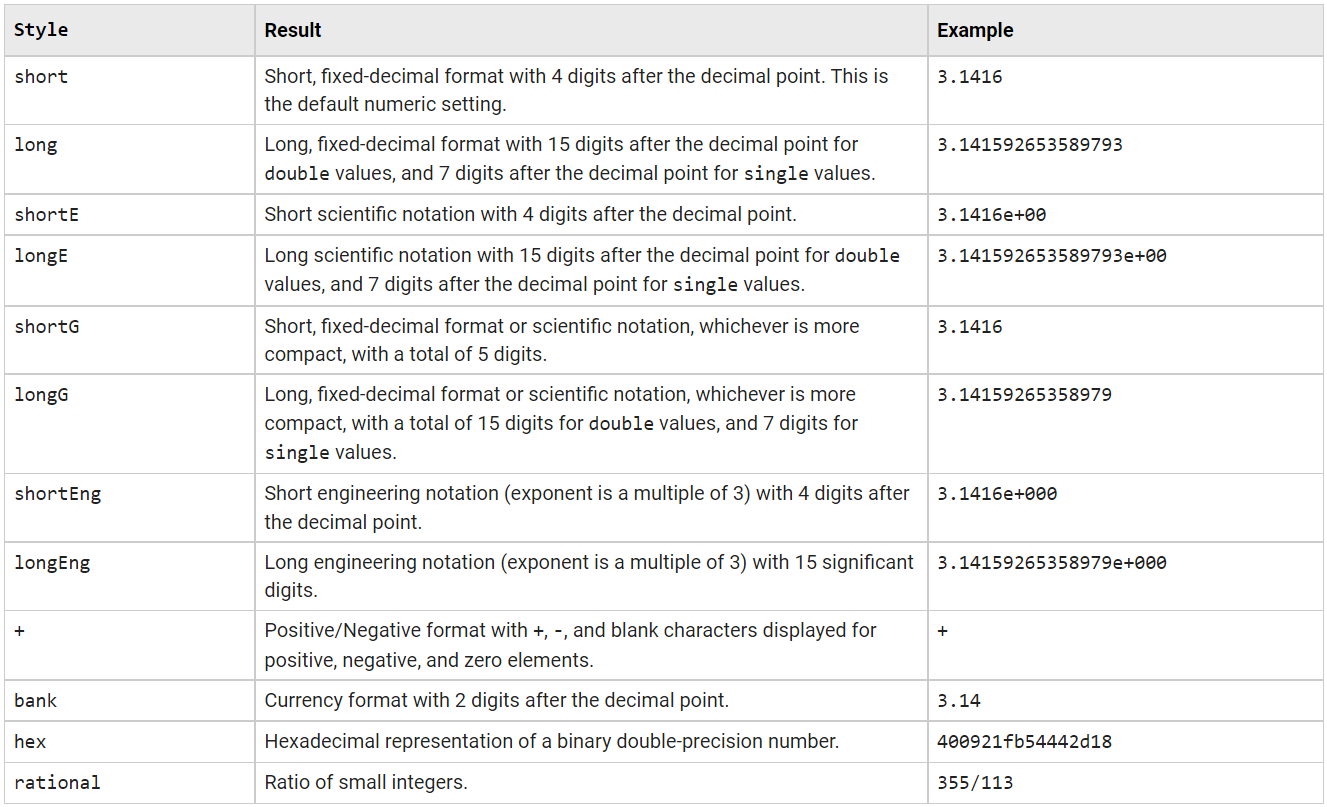

*Tomado de *[*MathWorks: *`format`](https://www.mathworks.com/help/matlab/ref/format.html)

El estilo predeterminado de MATLAB es `short`, pero evidentemente podemos cambiarlo. Una vez se haya cambiado, el estilo se matendrá dentro de MATLAB hasta que se indiqué un nuevo estilo o se reestablezca el estilo por defecto (que es el estilo `short`).

clear

% Crear un número.
n = 10410020.5;

% Visualización con estilo predeterminado: short.
n
% Visualización con estilo long.
format long
n
% Visualización con estilo shortE.
format shortE
n
% Visualización con estilo shortEng.
format shortEng
n
% Visualización con estilo bank.
format bank
n
% Reestablecimiento del estilo por defecto.
format default
n

## Constantes y números especiales

MATLAB provee de algunas constantes y representaciones de números especiales que es importante conocer puesto que pueden surgir de algunas operaciones elementales.

Éstas son:

- Número $\pi$$\Longrightarrow$`pi`.

- Número de Euler $e$$\Longrightarrow$`exp(1)`.

- Representación de un número faltante: **N**ot **a** **N**umber$\Longrightarrow$`NaN`.

- Representación de una fecha faltante: **N**ot **a** **T**ime$\Longrightarrow$`NaT`.

- **Inf**inito$\Longrightarrow$`Inf`. 

- Unidad **i**maginaria $i=\sqrt{-1}\Longrightarrow$`i` o `j`.

## Material adicional

- [Tipos de datos numéricos](https://www.mathworks.com/help/matlab/numeric-types.html)

- [Operaciones aritméticas](https://www.mathworks.com/help/matlab/arithmetic.html)

- [División euclídea o entera (Wikipedia)](https://es.wikipedia.org/wiki/Divisi%C3%B3n_eucl%C3%ADdea)

- [Diferencias entre `mod` y `rem`](https://www.mathworks.com/help/matlab/ref/rem.html#bu444r1-2)

- [Precedencia de operadores](https://www.mathworks.com/help/matlab/matlab_prog/operator-precedence.html)

- [Número complejo (Wikipedia)](https://es.wikipedia.org/wiki/N%C3%BAmero_complejo)

- [Números complejos en MATLAB](https://www.mathworks.com/help/matlab/complex-numbers.html)